# Introducción a la cuantificación escalar y vectorial

addpath('./datos')
addpath('./funciones')

## Cuantificación uniforme (para un vector)

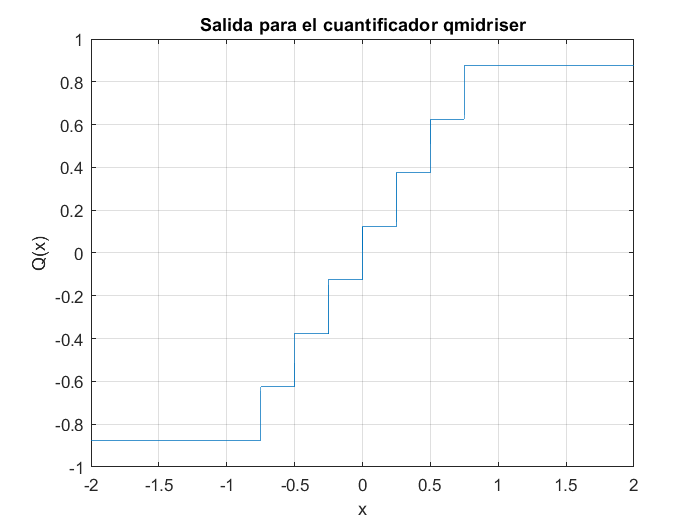

x = -2:0.001:2; xsc = 1;  n = 3;

[y_QMR, e_QMR] = qmidriser(x, xsc, n);
[y_QMT, e_QMT] = qmidtread(x, xsc, n);

plot (x, y_QMR), grid on, xlabel('x'), ylabel('Q(x)'), title('Salida para el cuantificador qmidriser');

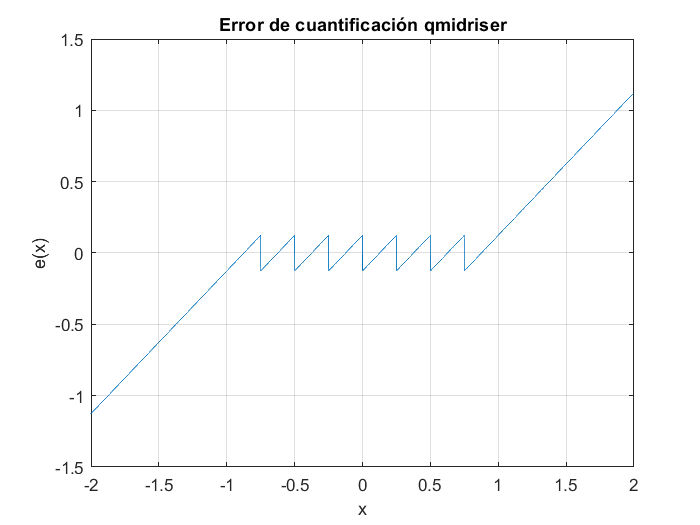

plot (x, e_QMR), grid on, xlabel('x'), ylabel('e(x)'), title('Error de cuantificación qmidriser');

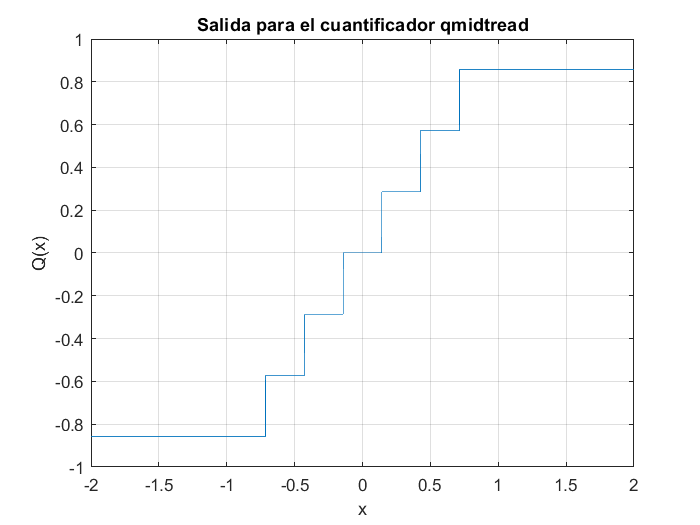


plot (x, y_QMT), grid on, xlabel('x'), ylabel('Q(x)'), title('Salida para el cuantificador qmidtread');

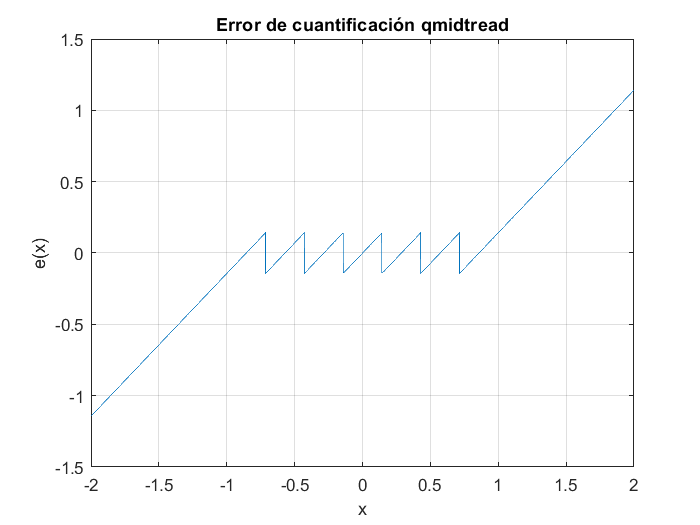

plot (x, e_QMT), grid on, xlabel('x'), ylabel('e(x)'), title('Error de cuantificación qmidtread');

## Cuantificación uniforme (para señales)

xsc = 1;
[Afonso_8kHz, fs] = audioread('Afonso_8khz.wav');
%sound(Afonso_8kHz);
[Gala_8kHz, fs] = audioread('Gala_8khz.wav');
%sound(Gala_8kHz);

### **Cuantificación a 8 bits**

#### `Afonso`

% n = 8;
% % > Con qmidriser()

% [Afonso_QMR_8b, e_Afonso_QMR_8b] = qmidriser(Afonso_8kHz, xsc, n), sound(Afonso_QMR_8b);
% figure, subplot 211, hold on, plot(e_Afonso_QMR_8b), title('Error Afonso con QMR a 8 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_QMR_8b);
% figure, subplot 211, hold on, plot(e_Afonso_QMR_8b), title('Error Afonso con QMR a 8 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_8kHz);
% clf, plot(e_Afonso_QMR_8b), title('Error Afonso con QMR a 8 bits'), xlabel('n'), ylabel('e(n)')

% % > Con qmidtread()

% [Afonso_QMT_8b, e_Afonso_QMT_8b] = qmidtread(Afonso_8kHz, xsc, n), sound(Afonso_QMT_8b);
% figure, subplot 211, hold on, plot(e_Afonso_QMT_8b), title('Error Afonso con QMT a 8 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_QMT_8b);
% clf, plot(e_Afonso_QMT_8b), title('Error Afonso con QMT a 8 bits'), xlabel('n'), ylabel('e(n)');

#### `GALA`

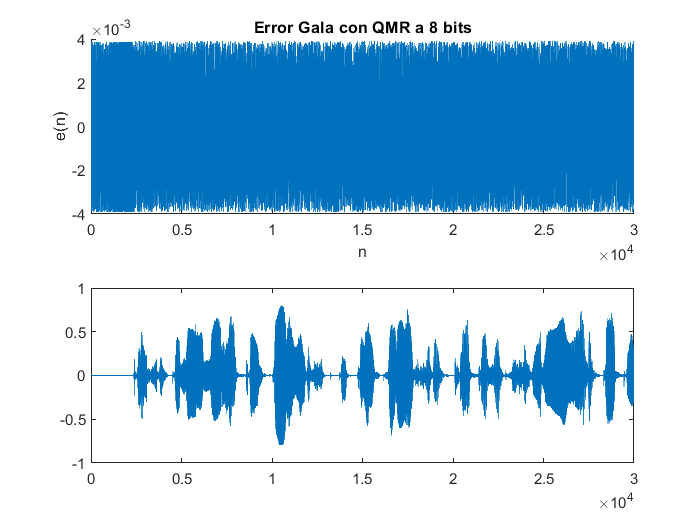

n = 8;
%% > Con qmidriser()

[Gala_QMR_8b, e_Gala_QMR_8b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_8b);

figure, subplot 211, hold on, plot(e_Gala_QMR_8b(1:30000)),title('Error Gala con QMR a 8 bits'), 
hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Gala_QMR_8b(1:30000)), hold off,

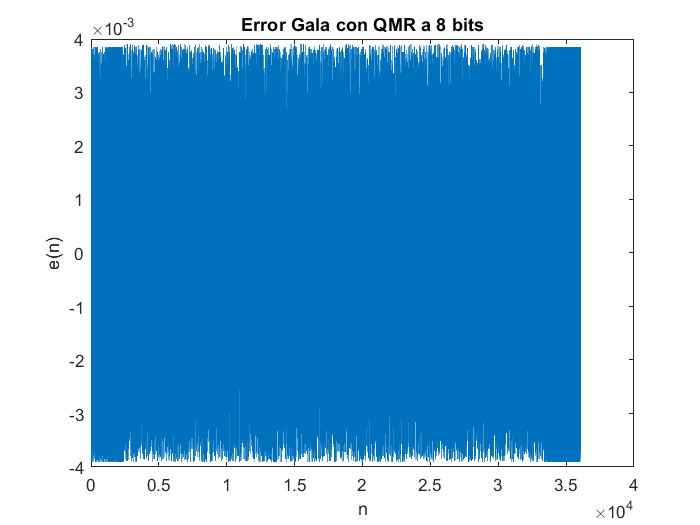

clf, plot(e_Gala_QMR_8b), title('Error Gala con QMR a 8 bits'), xlabel('n'), ylabel('e(n)')

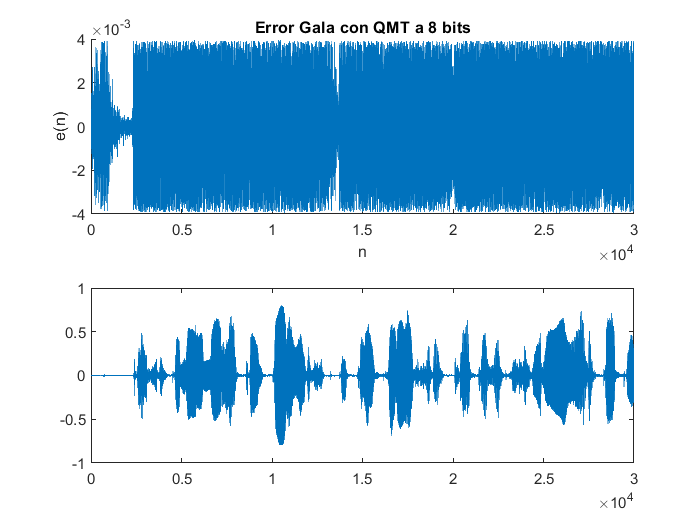


%% > Con qmidtread()

[Gala_QMT_8b, e_Gala_QMT_8b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_8b);
figure,subplot 211, hold on, plot(e_Gala_QMT_8b(1:30000)), title('Error Gala con QMT a 8 bits'),
hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Gala_QMT_8b(1:30000))

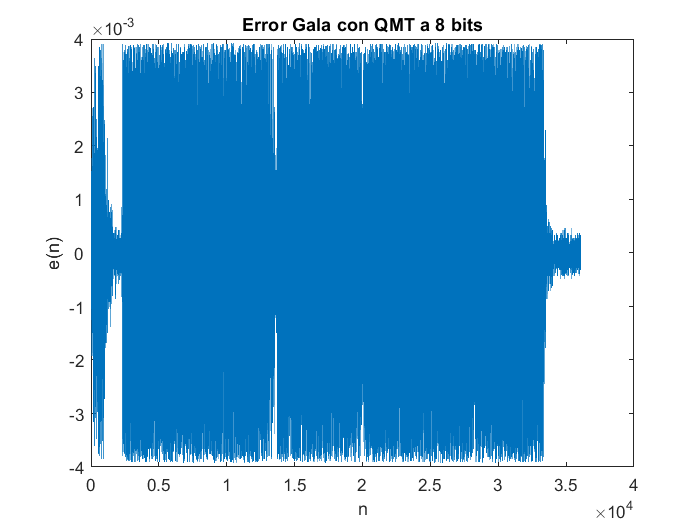

clf, plot(e_Gala_QMT_8b), title('Error Gala con QMT a 8 bits'),xlabel('n'),ylabel('e(n)'),

### **Cuantificación a 4 bits**

#### `AFONSO`

% n = 4;
% % > Con qmidriser()

% [Afonso_QMR_4b, e_Afonso_QMR_4b] = qmidriser(Afonso_8kHz, xsc, n), sound(Afonso_QMR_4b);
% figure, subplot 211, hold on, plot(e_Afonso_QMR_4b), title('Error Afonso con QMR a 4 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_QMR_4b);
% figure, subplot 211, hold on, plot(e_Afonso_QMR_4b), title('Error Afonso con QMR a 4 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_8kHz);
% clf, plot(e_Afonso_QMR_4b), title('Error Afonso con QMR a 4 bits'), xlabel('n'), ylabel('e(n)')

% % > Con qmidtread()

% [Afonso_QMT_4b, e_Afonso_QMT_4b] = qmidtread(Afonso_8kHz, xsc, n), sound(Afonso_QMT_4b);
% figure, subplot 211, hold on, plot(e_Afonso_QMT_4b), title('Error Afonso con QMT a 4 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_QMT_4b);
% clf, plot(e_Afonso_QMT_4b), title('Error Afonso con QMT a 4 bits'), xlabel('n'), ylabel('e(n)');

#### `GALA`

n = 4;
% > Con qmidriser()

[Gala_QMR_4b, e_Gala_QMR_4b] = qmidriser(Gala_8kHz, xsc, n), sound(Gala_QMR_4b);

Gala_QMR_4b =    -0.0625    0.0625    0.0625   -0.0625   -0.0625    0.0625    0.0625   -0.0625   -0.0625    0.0625    0.0625   -0.0625   -0.0625   -0.0625    0.0625   -0.0625   -0.0625    0.0625    0.0625    0.0625    0.0625   -0.0625   -0.0625    0.0625    0.0625    0.0625   -0.0625   -0.0625   -0.0625    0.0625    0.0625   -0.0625   -0.0625    0.0625    0.0625    0.0625   -0.0625   -0.0625   -0.0625    0.0625    0.0625   -0.0625   -0.0625   -0.0625    0.0625   -0.0625   -0.0625   -0.0625    0.0625    0.0625


e_Gala_QMR_4b =     0.0624   -0.0617   -0.0623    0.0617    0.0623   -0.0621   -0.0619    0.0622    0.0619   -0.0624   -0.0622    0.0619    0.0624    0.0615   -0.0623    0.0623    0.0621   -0.0624   -0.0620   -0.0617   -0.0624    0.0617    0.0620   -0.0623   -0.0622   -0.0620    0.0617    0.0623    0.0624   -0.0622   -0.0625    0.0623    0.0623   -0.0624   -0.0610   -0.0619    0.0622    0.0620    0.0621   -0.0617   -0.0618    0.0619    0.0621    0.0624   -0.0614    0.0622    0.0612    0.0618   -0.0622   -0.0610


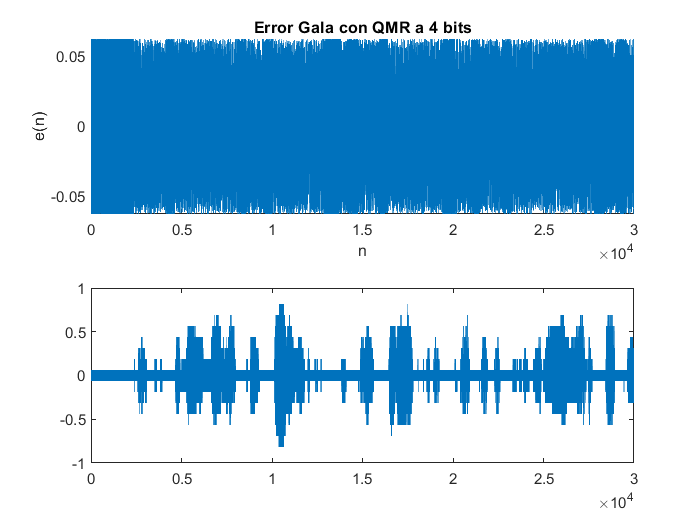


figure, subplot 211, hold on, plot(e_Gala_QMR_4b(1:30000)), title('Error Gala con QMR a 4 bits'),
hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Gala_QMR_4b(1:30000)),

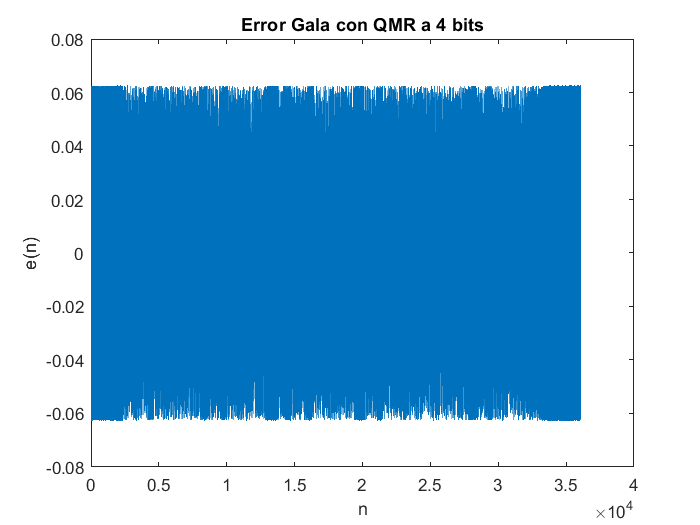

clf,plot(e_Gala_QMR_4b),title('Error Gala con QMR a 4 bits'),xlabel('n'),ylabel('e(n)'),


%% > Con qmidtread()
[Gala_QMT_4b, e_Gala_QMT_4b] = qmidtread(Gala_8kHz, xsc, n), sound(Gala_QMT_4b);

Gala_QMT_4b =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e_Gala_QMT_4b =    -0.0001    0.0008    0.0002   -0.0008   -0.0002    0.0004    0.0006   -0.0003   -0.0006    0.0001    0.0003   -0.0006   -0.0001   -0.0010    0.0002   -0.0002   -0.0004    0.0001    0.0005    0.0008    0.0001   -0.0008   -0.0005    0.0002    0.0003    0.0005   -0.0008   -0.0002   -0.0001    0.0003         0   -0.0002   -0.0002    0.0001    0.0015    0.0006   -0.0003   -0.0005   -0.0004    0.0008    0.0007   -0.0006   -0.0004   -0.0001    0.0011   -0.0003   -0.0013   -0.0007    0.0003    0.0015


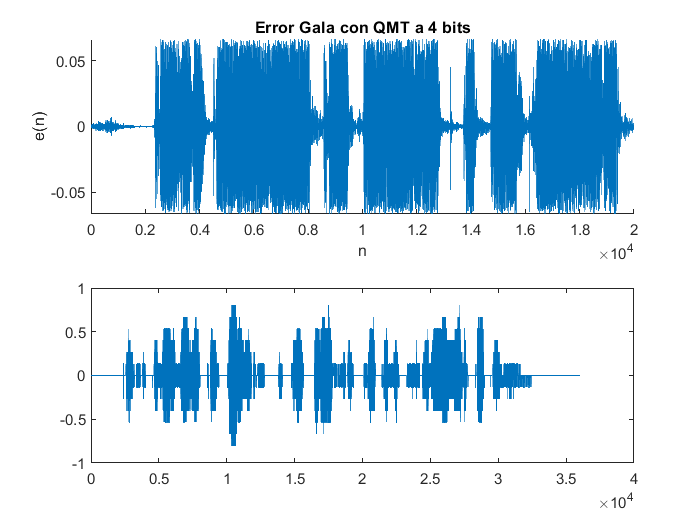


figure,subplot 211,hold on,plot(e_Gala_QMT_4b(1:20000)),title('Error Gala con QMT a 4 bits'),
hold off,xlabel('n'), ylabel('e(n)'), subplot 212, plot(Gala_QMT_4b),

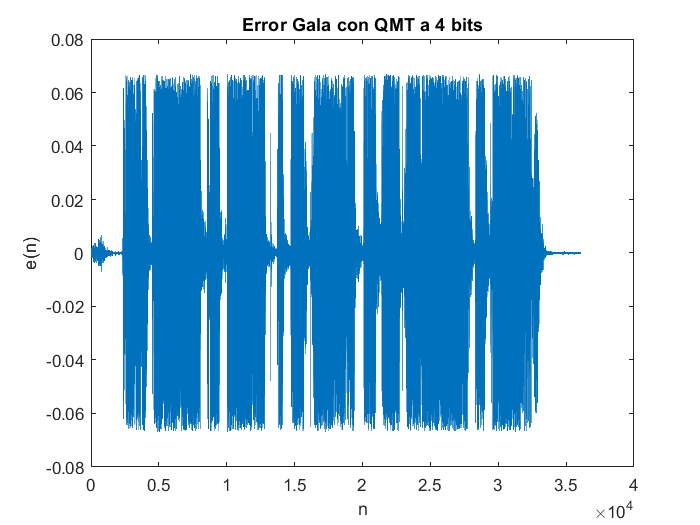

clf,plot(e_Gala_QMT_4b),title('Error Gala con QMT a 4 bits'),xlabel('n'),ylabel('e(n)'),

### Cuantificación a 2 bits

#### `AFONSO`

% n = 2;
% % > Con qmidriser()

% [Afonso_QMR_2b, e_Afonso_QMR_2b] = qmidriser(Afonso_8kHz, xsc, n), sound(Afonso_QMR_2b);
% figure, subplot 211, hold on, plot(e_Afonso_QMR_8b), title('Error Afonso con QMR a 2 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_QMR_2b);
% figure, subplot 211, hold on, plot(e_Afonso_QMR_8b), title('Error Afonso con QMR a 2 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_8kHz);
% clf, plot(e_Afonso_QMR_8b), title('Error Afonso con QMR a 8 bits'), xlabel('n'), ylabel('e(n)')

% % > Con qmidtread()

% [Afonso_QMT_2b, e_Afonso_QMT_2b] = qmidtread(Afonso_8kHz, xsc, n), sound(Afonso_QMT_2b);
% figure, subplot 211, hold on, plot(e_Afonso_QMT_2b), title('Error Afonso con QMT a 2 bits'), hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Afonso_QMT_2b);
% clf, plot(e_Afonso_QMT_2b), title('Error Afonso con QMT a 2 bits'), xlabel('n'), ylabel('e(n)');

#### `GALA`

n = 2;
%% > Con qmidriser()

[Gala_QMR_2b, e_Gala_QMR_2b] = qmidriser(Gala_8kHz, xsc, n),sound(Gala_QMR_2b);

Gala_QMR_2b =    -0.2500    0.2500    0.2500   -0.2500   -0.2500    0.2500    0.2500   -0.2500   -0.2500    0.2500    0.2500   -0.2500   -0.2500   -0.2500    0.2500   -0.2500   -0.2500    0.2500    0.2500    0.2500    0.2500   -0.2500   -0.2500    0.2500    0.2500    0.2500   -0.2500   -0.2500   -0.2500    0.2500    0.2500   -0.2500   -0.2500    0.2500    0.2500    0.2500   -0.2500   -0.2500   -0.2500    0.2500    0.2500   -0.2500   -0.2500   -0.2500    0.2500   -0.2500   -0.2500   -0.2500    0.2500    0.2500


e_Gala_QMR_2b =     0.2499   -0.2492   -0.2498    0.2492    0.2498   -0.2496   -0.2494    0.2497    0.2494   -0.2499   -0.2497    0.2494    0.2499    0.2490   -0.2498    0.2498    0.2496   -0.2499   -0.2495   -0.2492   -0.2499    0.2492    0.2495   -0.2498   -0.2497   -0.2495    0.2492    0.2498    0.2499   -0.2497   -0.2500    0.2498    0.2498   -0.2499   -0.2485   -0.2494    0.2497    0.2495    0.2496   -0.2492   -0.2493    0.2494    0.2496    0.2499   -0.2489    0.2497    0.2487    0.2493   -0.2497   -0.2485


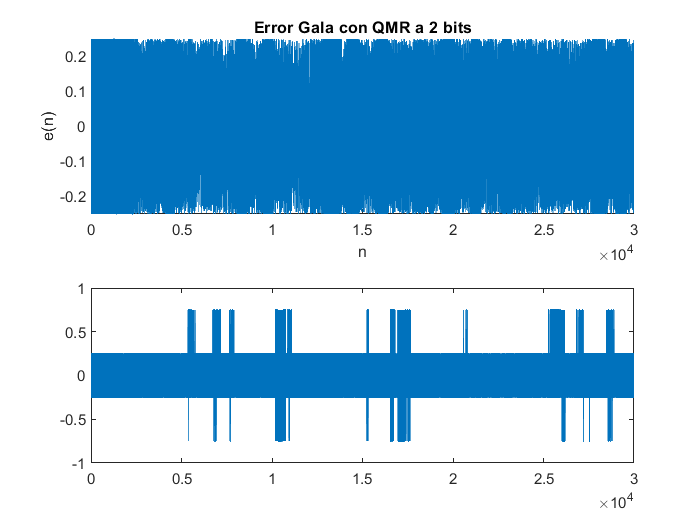


figure,subplot 211,hold on,plot(e_Gala_QMR_2b(1:30000)),title('Error Gala con QMR a 2 bits'),
hold off,xlabel('n'),ylabel('e(n)'),subplot 212,plot(Gala_QMR_2b(1:30000)),

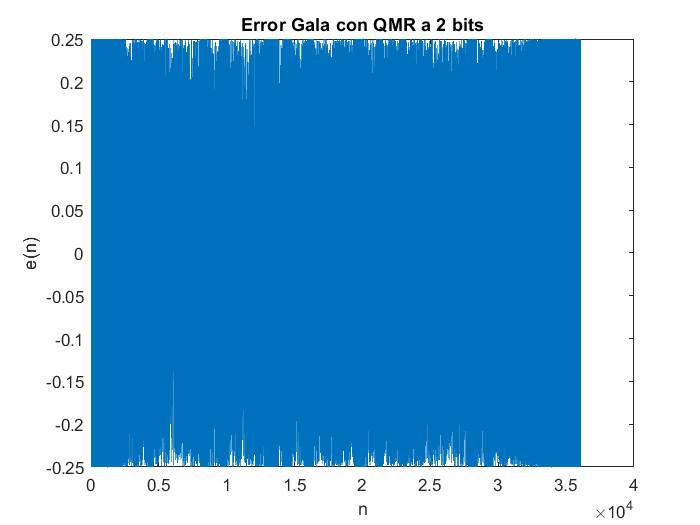

clf,plot(e_Gala_QMR_2b),title('Error Gala con QMR a 2 bits'),xlabel('n'),ylabel('e(n)')

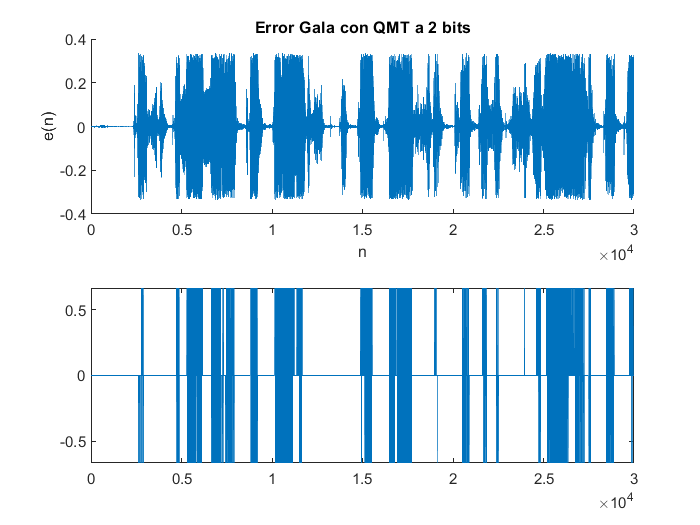


%% > Con qmidtread()

[Gala_QMT_2b, e_Gala_QMT_2b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_2b);

figure,subplot 211,hold on,plot(e_Gala_QMT_2b(1:30000)),title('Error Gala con QMT a 2 bits'),
hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Gala_QMT_2b(1:30000)),

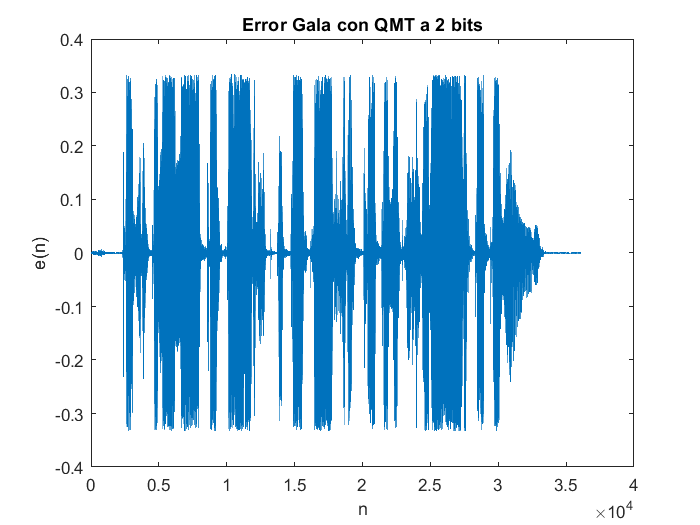

clf,plot(e_Gala_QMT_2b),title('Error Gala con QMT a 2 bits'),xlabel('n'),ylabel('e(n)'),


% e_A_QMT_2b=max(e_Afonso_QMT_2b)
% e_A_QMR_2b=max(e_Afonso_QMR_2b)
e_G_QMT_2b=max(e_Gala_QMT_2b),e_G_QMR_2b=max(e_Gala_QMR_2b)

e_G_QMT_2b = 0.3333

e_G_QMR_2b = 0.2499

### **Para 8 bits y xsc = 0.55**

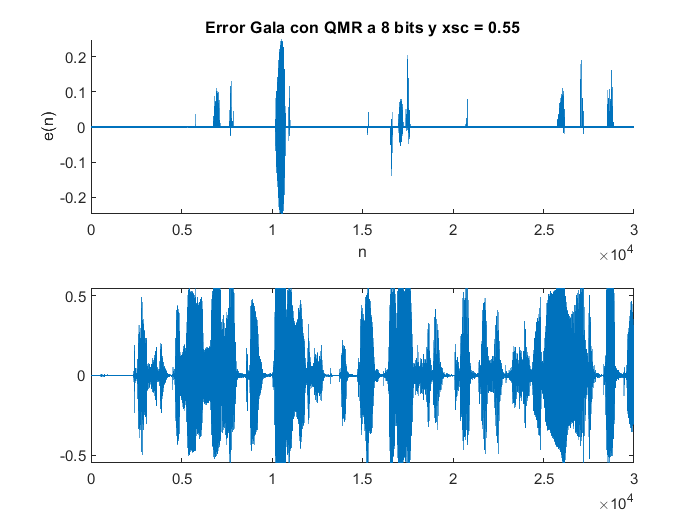

n = 8;
xsc = 0.55;
% > Con qmidriser()

[Gala_QMR_8b, e_Gala_QMR_8b] = qmidriser(Gala_8kHz, xsc, n);
%sound(Gala_QMR_8b);
% > Con qmidtread()

[Gala_QMT_8b, e_Gala_QMT_8b] = qmidtread(Gala_8kHz, xsc, n);
%sound(Gala_QMT_8b);

% >> Representación del error usando midriser
figure, subplot 211, hold on, plot(e_Gala_QMR_8b(1:30000)), title('Error Gala con QMR a 8 bits y xsc = 0.55'),
hold off, xlabel('n'), ylabel('e(n)'), subplot 212, plot(Gala_QMR_8b(1:30000)),

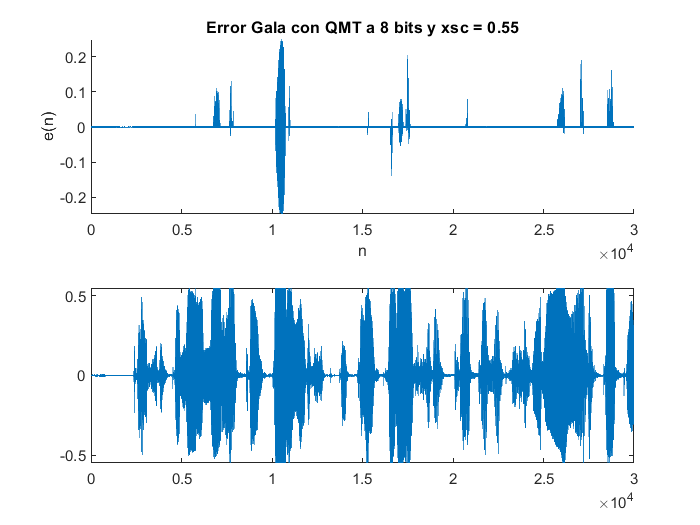


% >> Representación del error usando midtread
figure, subplot 211,hold on,plot(e_Gala_QMT_8b(1:30000)),title('Error Gala con QMT a 8 bits y xsc = 0.55'),
hold off,xlabel('n'),ylabel('e(n)'),subplot 212,plot(Gala_QMT_8b(1:30000))

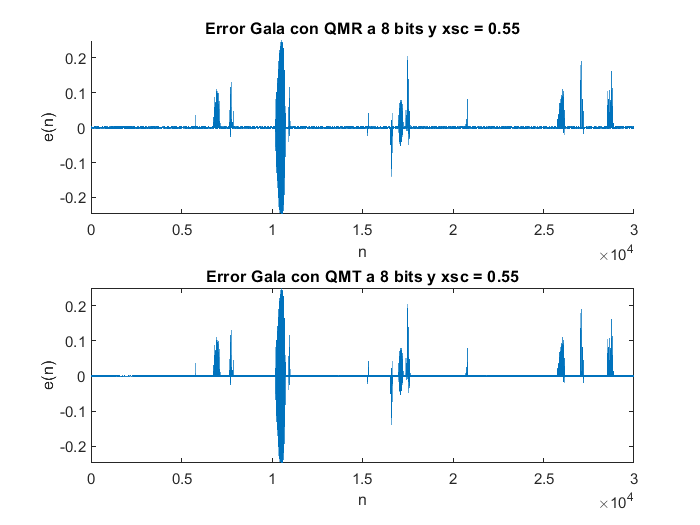

e_G_QMR_8b = 0.2504

e_G_QMT_8b = 0.0627

figure,subplot 211,hold on,plot(e_Gala_QMR_8b(1:30000)),title('Error Gala con QMR a 8 bits y xsc = 0.55'),
hold off,xlabel('n'),ylabel('e(n)'),subplot 212,plot(e_Gala_QMT_8b(1:30000)),title('Error Gala con QMT a 8 bits y xsc = 0.55'),
xlabel('n'), ylabel('e(n)'), e_G_QMR_8b=max(e_Gala_QMR_8b), e_G_QMT_8b=max(e_Gala_QMT_8b)*e_G_QMR_8b,

### **Para 8 bits y xsc = 0.3**

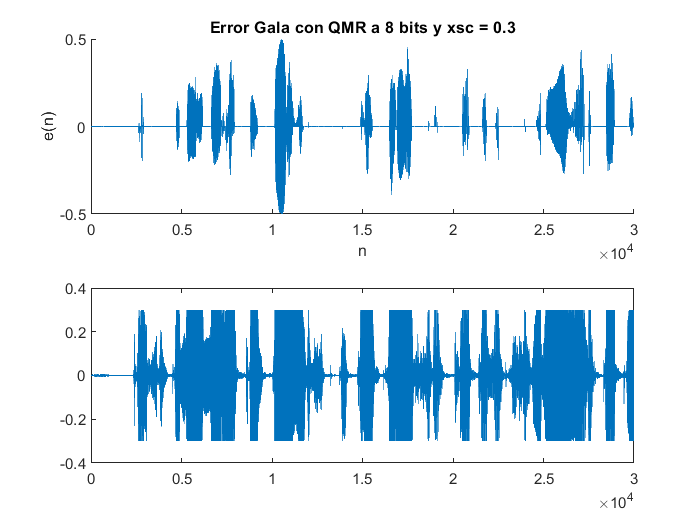

xsc = 0.3;
% > Con qmidriser()

[Gala_QMR_8b, e_Gala_QMR_8b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_8b);

% > Con qmidtread()

[Gala_QMT_8b, e_Gala_QMT_8b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_8b);

% >> Representación del error usando midriser
figure,subplot 211,hold on,plot(e_Gala_QMR_8b(1:30000)),title('Error Gala con QMR a 8 bits y xsc = 0.3')
hold off,xlabel('n'),ylabel('e(n)'),subplot 212,plot(Gala_QMR_8b(1:30000))

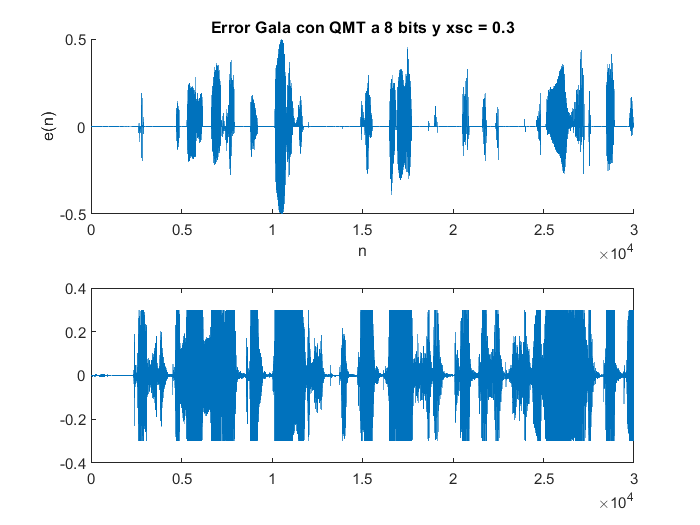

% >> Representación del error usando midtread
figure,subplot 211,hold on,plot(e_Gala_QMT_8b(1:30000)),title('Error Gala con QMT a 8 bits y xsc = 0.3')
hold off,xlabel('n'),ylabel('e(n)'),subplot 212,plot(Gala_QMT_8b(1:30000))

## Relación señal-ruido

Para el fichero Gala_8kHz.wav, con qmidriser() y qmidtread() de la tarea 1 con xsc=1:

- Obtened la SNR global, la SNR segmental y SNR por tramas. Representad junto a la señal original de forma análoga a “Ejemplo 2”. Utilizad n = 6 y L = 150. 

- Explicad las variaciones de la SNR por tramas. ¿En qué tramos de la señal es mayor? ¿Es posible que en alguna trama sea cero? 

### `Midriser() XSC=1 `

n = 6, xsc=1;

n = 6


[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n), sound(Gala_QMR_6b);

Gala_QMR_6b =    -0.0156    0.0156    0.0156   -0.0156   -0.0156    0.0156    0.0156   -0.0156   -0.0156    0.0156    0.0156   -0.0156   -0.0156   -0.0156    0.0156   -0.0156   -0.0156    0.0156    0.0156    0.0156    0.0156   -0.0156   -0.0156    0.0156    0.0156    0.0156   -0.0156   -0.0156   -0.0156    0.0156    0.0156   -0.0156   -0.0156    0.0156    0.0156    0.0156   -0.0156   -0.0156   -0.0156    0.0156    0.0156   -0.0156   -0.0156   -0.0156    0.0156   -0.0156   -0.0156   -0.0156    0.0156    0.0156


e_Gala_QMR_6b =     0.0156   -0.0149   -0.0154    0.0148    0.0154   -0.0152   -0.0150    0.0154    0.0150   -0.0156   -0.0153    0.0150    0.0156    0.0146   -0.0155    0.0155    0.0153   -0.0155   -0.0151   -0.0148   -0.0156    0.0148    0.0151   -0.0155   -0.0153   -0.0152    0.0148    0.0154    0.0155   -0.0154   -0.0156    0.0154    0.0154   -0.0155   -0.0141   -0.0150    0.0154    0.0151    0.0152   -0.0149   -0.0150    0.0150    0.0152    0.0156   -0.0145    0.0154    0.0144    0.0149   -0.0154   -0.0141


SNRq = SNR(Gala_8kHz,Gala_QMR_6b), [SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

SNRq = 23.7678

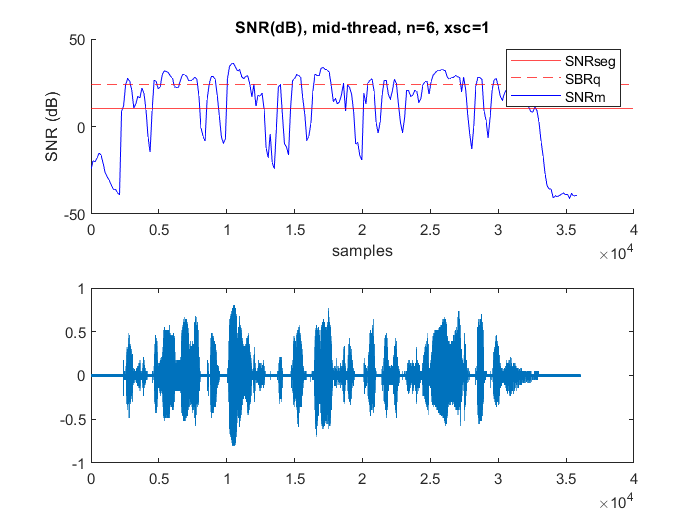


%plot (SNRm,SNRq,SNRseg)
figure, subplot 211, hold on, yline(SNRseg,'r'), yline(SNRq,'r--'), plot(m,SNRm,'b'),
legend('SNRseg','SBRq','SNRm'), title('SNR(dB), mid-thread, n=6, xsc=1'), hold off,
xlabel('samples'), ylabel('SNR (dB)'), subplot 212, plot(Gala_QMR_6b);

### `Midtread() XSC=1`

[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n), sound(Gala_QMT_6b);

Gala_QMT_6b =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e_Gala_QMT_6b =    -0.0001    0.0008    0.0002   -0.0008   -0.0002    0.0004    0.0006   -0.0003   -0.0006    0.0001    0.0003   -0.0006   -0.0001   -0.0010    0.0002   -0.0002   -0.0004    0.0001    0.0005    0.0008    0.0001   -0.0008   -0.0005    0.0002    0.0003    0.0005   -0.0008   -0.0002   -0.0001    0.0003         0   -0.0002   -0.0002    0.0001    0.0015    0.0006   -0.0003   -0.0005   -0.0004    0.0008    0.0007   -0.0006   -0.0004   -0.0001    0.0011   -0.0003   -0.0013   -0.0007    0.0003    0.0015


SNRq = SNR(Gala_8kHz,Gala_QMT_6b), [SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMT_6b,150);

SNRq = 26.2091

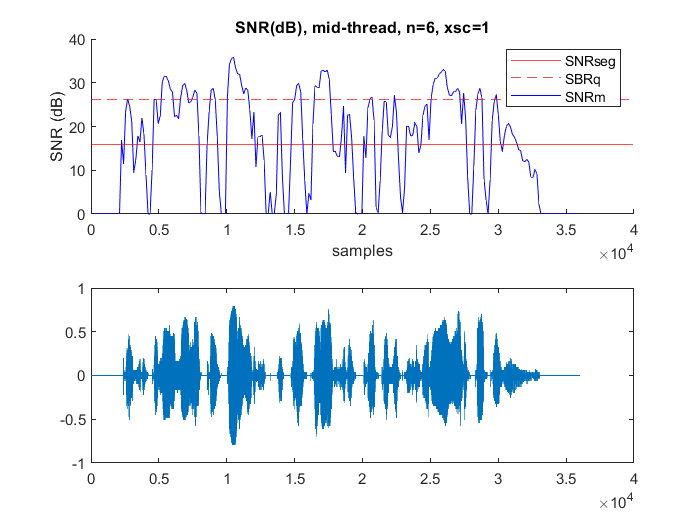


%plot (SNRm,SNRq,SNRseg)
figure, subplot 211, hold on, yline(SNRseg,'r'), yline(SNRq,'r--'), plot(m,SNRm,'b'),
legend('SNRseg','SBRq','SNRm'), title('SNR(dB), mid-thread, n=6, xsc=1'), hold off,
xlabel('samples'), ylabel('SNR (dB)'), subplot 212, plot(Gala_QMT_6b);

### `Midriser() XSC=0.55`

n = 6, xsc=0.55;

n = 6


[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n), sound(Gala_QMR_6b);

Gala_QMR_6b =    -0.0086    0.0086    0.0086   -0.0086   -0.0086    0.0086    0.0086   -0.0086   -0.0086    0.0086    0.0086   -0.0086   -0.0086   -0.0086    0.0086   -0.0086   -0.0086    0.0086    0.0086    0.0086    0.0086   -0.0086   -0.0086    0.0086    0.0086    0.0086   -0.0086   -0.0086   -0.0086    0.0086    0.0086   -0.0086   -0.0086    0.0086    0.0086    0.0086   -0.0086   -0.0086   -0.0086    0.0086    0.0086   -0.0086   -0.0086   -0.0086    0.0086   -0.0086   -0.0086   -0.0086    0.0086    0.0086


e_Gala_QMR_6b =     0.0085   -0.0078   -0.0084    0.0078    0.0084   -0.0082   -0.0080    0.0083    0.0080   -0.0085   -0.0083    0.0080    0.0085    0.0076   -0.0084    0.0084    0.0082   -0.0085   -0.0080   -0.0078   -0.0085    0.0078    0.0081   -0.0084   -0.0083   -0.0081    0.0078    0.0084    0.0085   -0.0083   -0.0086    0.0084    0.0084   -0.0085   -0.0071   -0.0080    0.0083    0.0081    0.0082   -0.0078   -0.0079    0.0080    0.0082    0.0085   -0.0075    0.0083    0.0073    0.0079   -0.0083   -0.0071


SNRq = SNR(Gala_8kHz,Gala_QMR_6b), [SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

SNRq = 20.8461

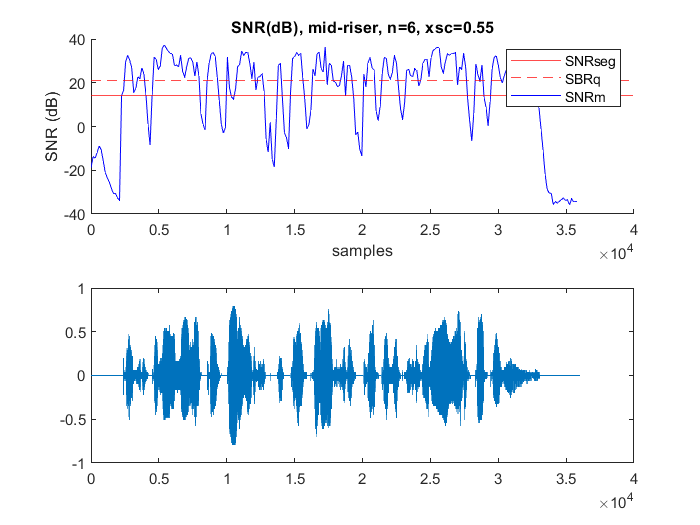


%plot (SNRm,SNRq,SNRseg)
figure, subplot 211, hold on, yline(SNRseg,'r'), yline(SNRq,'r--'), plot(m,SNRm,'b')
legend('SNRseg','SBRq','SNRm'), hold off, xlabel('samples'), ylabel('SNR (dB)'), 
title('SNR(dB), mid-riser, n=6, xsc=0.55'), subplot 212, plot(Gala_QMT_6b);

### `Midriser() XSC=0.3`

xsc=0.3;

[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n), sound(Gala_QMR_6b);

Gala_QMR_6b =    -0.0047    0.0047    0.0047   -0.0047   -0.0047    0.0047    0.0047   -0.0047   -0.0047    0.0047    0.0047   -0.0047   -0.0047   -0.0047    0.0047   -0.0047   -0.0047    0.0047    0.0047    0.0047    0.0047   -0.0047   -0.0047    0.0047    0.0047    0.0047   -0.0047   -0.0047   -0.0047    0.0047    0.0047   -0.0047   -0.0047    0.0047    0.0047    0.0047   -0.0047   -0.0047   -0.0047    0.0047    0.0047   -0.0047   -0.0047   -0.0047    0.0047   -0.0047   -0.0047   -0.0047    0.0047    0.0047


e_Gala_QMR_6b =     0.0046   -0.0039   -0.0045    0.0039    0.0045   -0.0043   -0.0040    0.0044    0.0040   -0.0046   -0.0044    0.0041    0.0046    0.0036   -0.0045    0.0045    0.0043   -0.0046   -0.0041   -0.0039   -0.0046    0.0039    0.0042   -0.0045   -0.0044   -0.0042    0.0039    0.0045    0.0046   -0.0044   -0.0047    0.0045    0.0045   -0.0046   -0.0032   -0.0040    0.0044    0.0042    0.0043   -0.0039   -0.0040    0.0040    0.0043    0.0046   -0.0036    0.0044    0.0034    0.0040   -0.0044   -0.0032


SNRq = SNR(Gala_8kHz,Gala_QMR_6b), [SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

SNRq = 9.6824

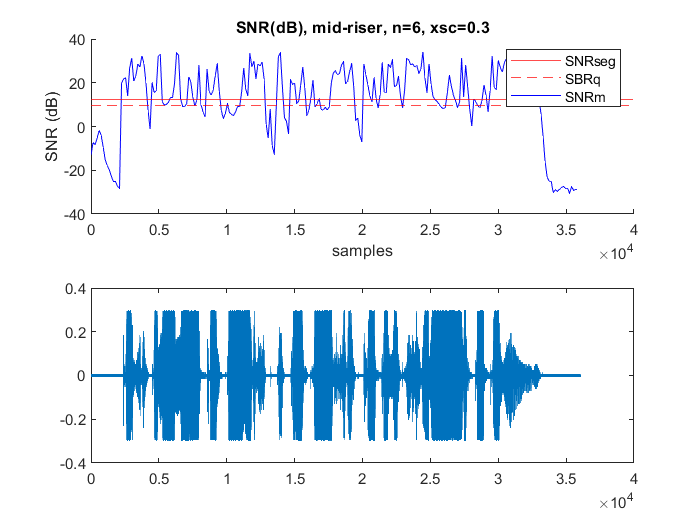


%plot (SNRm,SNRq,SNRseg)
figure, subplot 211, hold on, yline(SNRseg,'r'), yline(SNRq,'r--'), plot(m,SNRm,'b'),
legend('SNRseg','SBRq','SNRm'), hold off, xlabel('samples'), ylabel('SNR (dB)'),
title('SNR(dB), mid-riser, n=6, xsc=0.3'), subplot 212, plot(Gala_QMR_6b)

### `Midtread() XSC=0.55`

xsc=0.55;

[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n), sound(Gala_QMT_6b);

Gala_QMT_6b =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e_Gala_QMT_6b =    -0.0001    0.0008    0.0002   -0.0008   -0.0002    0.0004    0.0006   -0.0003   -0.0006    0.0001    0.0003   -0.0006   -0.0001   -0.0010    0.0002   -0.0002   -0.0004    0.0001    0.0005    0.0008    0.0001   -0.0008   -0.0005    0.0002    0.0003    0.0005   -0.0008   -0.0002   -0.0001    0.0003         0   -0.0002   -0.0002    0.0001    0.0015    0.0006   -0.0003   -0.0005   -0.0004    0.0008    0.0007   -0.0006   -0.0004   -0.0001    0.0011   -0.0003   -0.0013   -0.0007    0.0003    0.0015


SNRq = SNR(Gala_8kHz,Gala_QMT_6b), [SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMT_6b,150);

SNRq = 21.0734

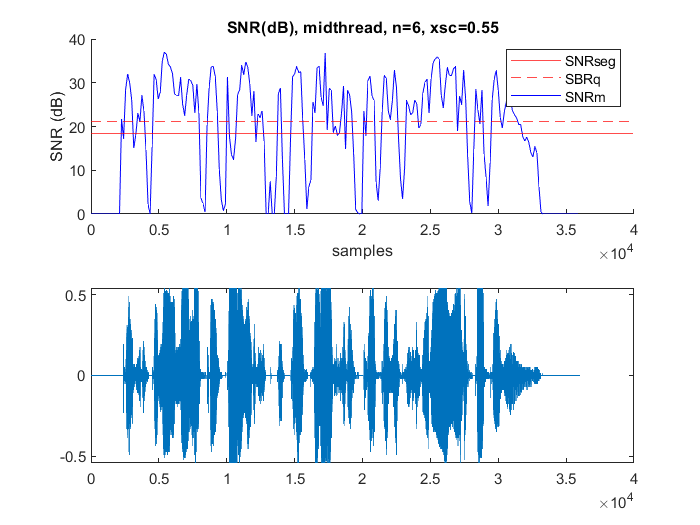


%plot (SNRm,SNRq,SNRseg)
figure, subplot 211, hold on, yline(SNRseg,'r'), yline(SNRq,'r--'), plot(m,SNRm,'b'),
legend('SNRseg','SBRq','SNRm'), hold off, xlabel('samples'), ylabel('SNR (dB)'),
title('SNR(dB), midthread, n=6, xsc=0.55'), subplot 212, plot(Gala_QMT_6b)

### `Midtread() XSC=0.3`

xsc=0.3;

[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n), sound(Gala_QMT_6b);

Gala_QMT_6b =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


e_Gala_QMT_6b =    -0.0001    0.0008    0.0002   -0.0008   -0.0002    0.0004    0.0006   -0.0003   -0.0006    0.0001    0.0003   -0.0006   -0.0001   -0.0010    0.0002   -0.0002   -0.0004    0.0001    0.0005    0.0008    0.0001   -0.0008   -0.0005    0.0002    0.0003    0.0005   -0.0008   -0.0002   -0.0001    0.0003         0   -0.0002   -0.0002    0.0001    0.0015    0.0006   -0.0003   -0.0005   -0.0004    0.0008    0.0007   -0.0006   -0.0004   -0.0001    0.0011   -0.0003   -0.0013   -0.0007    0.0003    0.0015


SNRq = SNR(Gala_8kHz,Gala_QMT_6b), [SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMT_6b,150);

SNRq = 9.6834

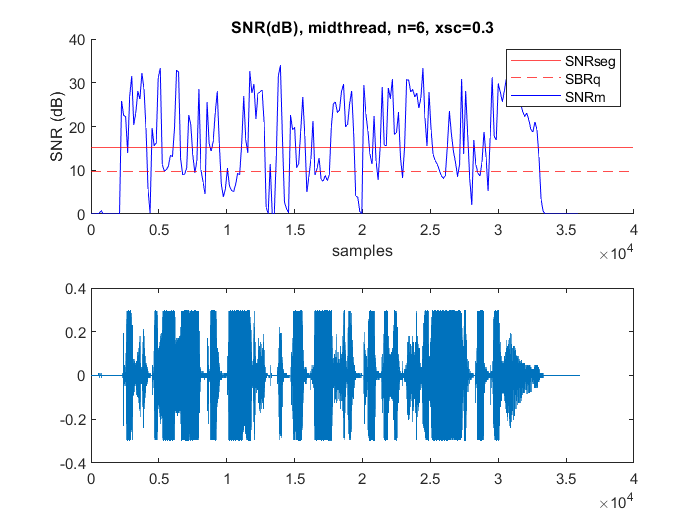


%plot (SNRm,SNRq,SNRseg)
figure, subplot 211, hold on, yline(SNRseg,'r'), yline(SNRq,'r--'), plot(m,SNRm,'b'),
legend('SNRseg','SBRq','SNRm'), hold off, xlabel('samples'), ylabel('SNR (dB)'),
title('SNR(dB), midthread, n=6, xsc=0.3'), subplot 212, plot(Gala_QMT_6b)

### `Midriser() N=1:8 XSC=1`

xsc=1;

for n=1:1:8
    [Afonso_QMR_nb, e_Afonso_QMR_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMR_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMR_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMR_nb,150);   
end

for n=1:1:8
    [Gala_QMR_nb, e_Gala_QMR_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMR_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMR_nb,150);   
end

n=1:1:8, Rb = 8*10^4*n;

n =      1     2     3     4     5     6     7     8



figure, plot(Rb,6.02*n,'k'), hold on, plot(Rb,6.02*n-7.27,'b'), hold on, plot(Rb,SNRq_A,'r--o'), ax = gca, ax.XTick = Rb, 

ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


grid, hold on, plot(Rb,SNRq_G,'g--+'), ax = gca, ax.XTick = Rb, xlabel('Rb(kbps)'), ylabel('SNR (dB)'), 

ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala'), title("SNR global, midriser, n=1:8,xsc=1,fs=8 kHz"), grid

### `Midtread() N=1:8 XSC=1`

xsc=1;

for n=1:1:8
    [Afonso_QMT_nb, e_Afonso_QMT_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMT_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMT_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMT_nb,150);   
end

for n=1:1:8
    [Gala_QMT_nb, e_Gala_QMT_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMT_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMT_nb,150);   
end

n=1:1:8, Rb = 8*10^4*n;

n =      1     2     3     4     5     6     7     8



figure, plot(Rb,6.02*n,'k'), hold on, plot(Rb,6.02*n-7.27,'b'), hold on, plot(Rb,SNRq_A,'r--o'), ax = gca, ax.XTick = Rb,

ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


grid, hold on, plot(Rb,SNRq_G,'g--+'), ax = gca, ax.XTick = Rb, xlabel('Rb(kbps)'), ylabel('SNR (dB)'), 

ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


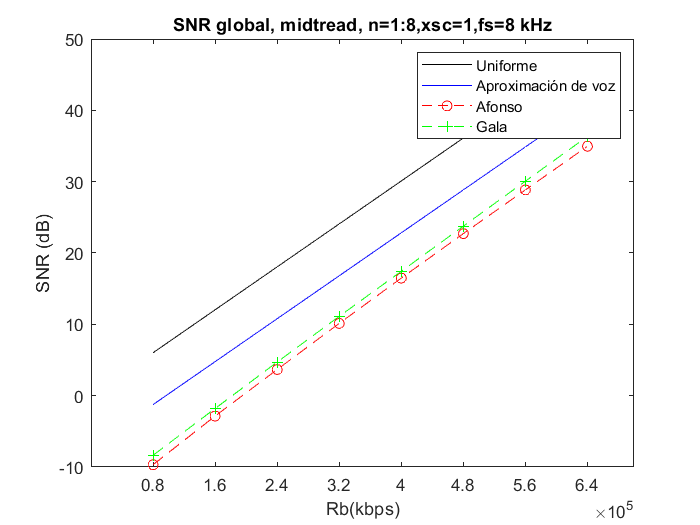

legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala'), title("SNR global, midtread, n=1:8,xsc=1,fs=8 kHz"), grid

### `Midriser() N=1:8 XSC=0.55`

xsc=0.55;

for n=1:1:8
    [Afonso_QMR_nb, e_Afonso_QMR_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMR_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMR_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMR_nb,150);   
end

for n=1:1:8
    [Gala_QMR_nb, e_Gala_QMR_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMR_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMR_nb,150);   
end

n=1:1:8, Rb = 8*10^4*n;

n =      1     2     3     4     5     6     7     8



figure, plot(Rb,6.02*n,'k'), hold on, plot(Rb,6.02*n-7.27,'b'), hold on, plot(Rb,SNRq_A,'r--o'), ax = gca; 
ax.XTick = Rb, grid, hold on;plot(Rb,SNRq_G,'g--+'), ax = gca, ax.XTick = Rb, xlabel('Rb(kbps)'), ylabel('SNR (dB)')

ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


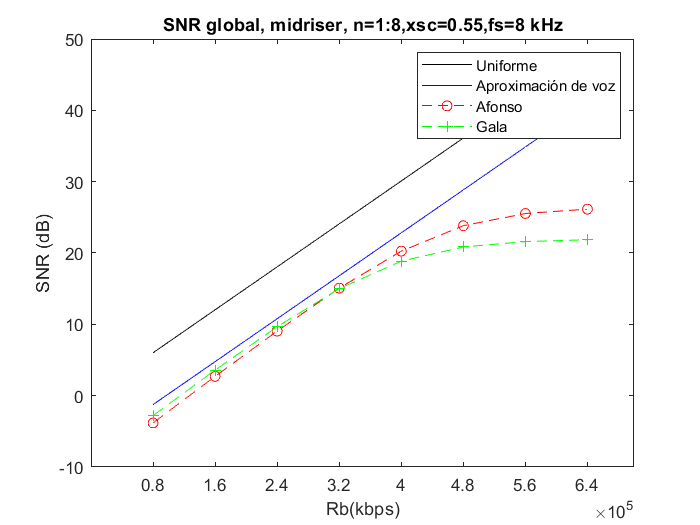

legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala'), title("SNR global, midriser, n=1:8,xsc=0.55,fs=8 kHz"), grid;

### `Midriser() N=1:8 XSC=0.3`

xsc=0.3;

for n=1:1:8
    [Afonso_QMT_nb, e_Afonso_QMT_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMT_nb);
    SNRq_A(1,n) = SNR(Afonso_8kHz,Afonso_QMT_nb);
    [SNRseg_A,SNRm_A,m_A] = SNRS(Afonso_8kHz,Afonso_QMT_nb,150);   
end
for n=1:1:8
    [Gala_QMT_nb, e_Gala_QMT_nb] = qmidriser(Gala_8kHz, xsc, n);
    sound(Gala_QMR_nb);
    SNRq_G(1,n) = SNR(Gala_8kHz,Gala_QMT_nb);
    [SNRseg_G,SNRm_G,m_G] = SNRS(Gala_8kHz,Gala_QMT_nb,150);   
end

n=1:1:8, Rb = 8*10^4*n;

n =      1     2     3     4     5     6     7     8


figure
plot(Rb,6.02*n,'k'), hold on, plot(Rb,6.02*n-7.27,'b'), hold on, plot(Rb,SNRq_A,'r--o'), ax = gca,

ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XTick = Rb, grid, hold on, plot(Rb,SNRq_G,'g--+'), ax = gca, ax.XTick = Rb, xlabel('Rb(kbps)'),ylabel('SNR (dB)'),

ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0 700000]
             YLim: [-10 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


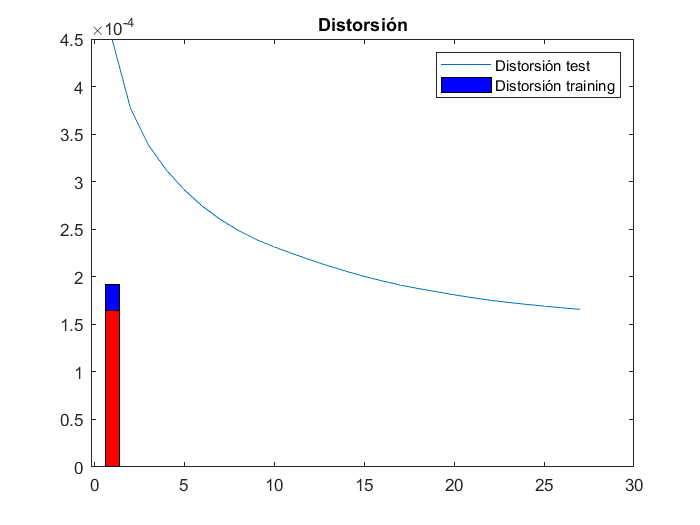

legend('Uniforme','Aproximación de voz', 'Afonso', 'Gala'),title("SNR global, midriser, n=1:8,xsc=0.3,fs=8 kHz"), grid

## Introducción a la cuantificación vectorial (VQ)

Con traindata.mat

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

[VQ vDist no_asig] = Kmeans(traindata, 6, [], 0.001, 1);

Representa cómo varía la distorsión obtenida, vDist, en función de la iteración

plot(vDist), title('Distorsión de una ejecución'), xlabel('Número de iteración'), ylabel(' ');

Ejecuta el algoritmo Kmeans 20 veces . Guarda el tiempo de ejecución y la distorsión de la última iteración de cada ejecución. Represéntalos gráficamente. (Ayuda: funciones Matlab clock y etime)

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

for i = 1:20
  horaInicial = clock;
  [VQ vDist no_asig] = Kmeans(traindata, 6, [], 0.001, 1);
  horaFinal = clock;
  vectorDistorsion(i,:) = vDist(length(vDist));
  vectorHoras(i,:) = etime(horaFinal, horaInicial);
end

subplot 211, plot(vectorDistorsion), title('Última distorsión de cada ejecución'),
subplot 211, stem(vectorHoras), title('Tiempo de ejecución'),xlabel('Número de ejecución')

Con tvg_training_20s.wav

[valores_training, fs_training] = audioread('tvg_training_20s.wav');
columna = 0; %para cambiar entre una columna y otra
fila = 1;

for i=1:length(valores_training)
    if columna == 0 %impar
        training(fila, 1) = valores_training (i);
        columna = 1;
    else %par
        training(fila, 2) = valores_training (i);
        columna = 0;
        fila = fila + 1;
    end
end

Diseñar un VQ de 6 bits (VQ6) con umbral=0.01

if isempty(gcp('nocreate'))
parpool;
end

[VQ6 vDist no_asig] = Kmeans(training, 6, [], 0.01, 1);
plot(vDist), title('Distorsión')

[valores_test, fs_test] = audioread('tvg_test_20s.wav');
columna = 0; %para cambiar entre una columna y otra
fila = 1;
for i=1:length(valores_test)
    if columna == 0 %impar
        test(fila, 1) = valores_test (i);
        columna = 1;
    else %par
        test(fila, 2) = valores_test (i);
        columna = 0;
        fila = fila + 1;
    end
end
save Tarea3.mat
tiempoEjecucion = sum(vectorHoras)

## Aplicación de un VQ previamente entrenado

Considera los ficheros tvg_training_20s.wav y tvg_test_20s.wav.

%[valores_training, fs_training] = audioread('tvg_training_20s.wav');
%[valores_test, fs_test] = audioread('tvg_test_20s.wav');
%load('traindata.mat')

if isempty(gcp('nocreate'))
parpool;
end

[y_training, Dist_training] = VQuantize(training,VQ6);
[y_test, Dist_test] = VQuantize(test,VQ6);

hold on, bar(Dist_test,'b'), bar(Dist_training,'r'), legend('Distorsión test', 'Distorsión training'), hold off
columna = 0; %reordenar en una fila el audio
fila = 1;

for i=1:length(valores_training)
    if columna == 0 %impar
        testReordenado (i) = y_test(fila, 1);
        columna = 1;
    else %par
        testReordenado (i) = y_test(fila, 2);
        columna = 0;
        fila = fila + 1;
    end
end

columna = 0; %reordenar en una fila el audio
fila = 1;

for i=1:length(valores_test)
    if columna == 0 %impar
        trainingReordenado (i) = y_training(fila, 1);
        columna = 1;
    else %par
        trainingReordenado (i) = y_training(fila, 2);
        columna = 0;
        fila = fila + 1;
    end
end


SNRtest = SNR(valores_test, testReordenado)
SNRtraining = SNR(valores_training, trainingReordenado)
save Tarea4.mat

## Comparación SNR algoritmo K-means

### 5a

load('Tarea4.mat')

umbral = 0.01, display=0; %no sacar grafica
VQini= [];

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

Obtén con Kmeans cuantificadores vectoriales de 1 a 16 bits (umbral = 0,01).

for nbits = 1 : 16
    horaInicial = clock;
    [VQ, vDist no_asig] = Kmeans (training, nbits, VQini, umbral, display);
    horaFinal=clock;
    vectorHorasEstimacion(nbits,:) = etime(horaFinal, horaInicial);

Almacena los 16 VQs en una única matriz VQt de forma que las dos primeras filas se correspondan con los centroides del VQ de 1 bit, las cuatro siguientes con los centroides del VQ de 2 bits, etc.

    if nbits == 1
        VQt = VQ;
    else 
        VQt = vertcat(VQt, VQ);
    end
end

Registra el tiempo que tarda en estimarse cada uno de los 16 VQs y represéntalo en función del número de bits.

horasEstimacion = sum(vectorHorasEstimacion)

n=1:1:16;
figure, plot(n,vectorHorasEstimacion), grid, xlabel('n(bits)'), ylabel('segundos estimación)'),
title("Tiempo que tarda en estimarse los VQs"), grid;

Guarda la matriz VQt y los tiempos registrados en el fichero VQt.mat.

save ('VQt.mat', 'VQt', 'vectorHorasEstimacion');
save 5a.mat

### **5b**

load ('VQt.mat', 'VQt', 'vectorHorasEstimacion');
[valores_training_5s, fs_training_5s] = audioread('tvg_training_5s.wav');
data_5s=reshape(valores_training_5s',2,length(valores_training_5s)/2)';
SNRq=[];

for nbits = 1:1:16
    
    % Extraigo de la matriz VQt las filas correspondientes al VQ de nbits
    % de la iteración correspondiente
    if nbits == 1
        filainicial = 1;
        filafinal = 2;
    else 
        filainicial = filainicial + 2^(nbits-1);
        filafinal = filainicial + 2^nbits - 1;      
    end
    
    VQi = VQt (filainicial:filafinal, :);
         dataq_5s = VQuantize (data_5s, VQi);
   
    % Pares de muestras a vector adecuadamente ordenado
    temp=dataq_5s';
        y_5s=temp(:);

    % Tenéis un traspuesto en vuestra SNR por lo que tengo que añadir:
    y_5s=y_5s';
    SNRq=[SNRq, SNR(valores_training_5s, y_5s)];
   
end

xsc=1;
for n=1:1:8
    [training_5s_QMR_nb, e_training_5s_QMR_nb] = qmidriser(valores_training_5s, xsc, n);
    SNRq_QMR(n) = SNR(valores_training_5s, training_5s_QMR_nb);
end

fs=8*10^3;
    
nb=1:1:16;
n=1:1:8; 
Rb_1a16 = fs*(nb/2);     % Rb entre [4 kB - 64 kB]
Rb_1a8 = fs*n;

figure, plot(Rb_1a8,6.02*n,'k'), hold on, plot(Rb_1a8,6.02*n-7.27,'b'), hold on,
%plot(Rb,SNRq(1:length(Rb)),'r--o');
plot(Rb_1a16,SNRq,'r--o'),ax = gca, ax.XTick = Rb_1a16, grid, hold on,
plot(Rb_1a8,SNRq_QMR,'g--+'), ax = gca, ax.XTick = Rb_1a16,
legend({'SNR1','SNR2', 'SNR VQs','SNR qmidrisers'}, 'Location', 'northwest'),
title("SNR global (con cuantificadores vectoriales y midriser) para tvgtraining5s.wav "), grid,


### **5c**

load ('VQt.mat', 'VQt', 'vectorHorasEstimacion');
[valores_test_5s, fs_test_5s] = audioread('tvg_test_5s.wav');
data_5s=reshape(valores_test_5s',2,length(valores_test_5s)/2)';
SNRq=[];

for nbits = 1:1:16
    % Extraigo de la matriz VQt las filas correspondientes al VQ de nbits
    % de la iteración correspondiente
    if nbits == 1
        filainicial = 1;
        filafinal = 2;
    else 
        filainicial = filainicial + 2^(nbits-1);
        filafinal = filainicial + 2^nbits - 1;      
    end
    
    VQi = VQt (filainicial:filafinal, :)
    dataq_5s = VQuantize (data_5s, VQi);
    
    % Pares de muestras a vector adecuadamente ordenado
    temp=dataq_5s';
    y_5s=temp(:);

    % Tenéis un traspuesto en vuestra SNR por lo que tengo que añadir:
    y_5s=y_5s';
    SNRq=[SNRq, SNR(valores_test_5s, y_5s)];
   
end

xsc=1;
for n=1:1:8
    [test_5s_QMR_nb, e_test_5s_QMR_nb] = qmidriser(valores_test_5s, xsc, n);
    SNRq_QMR(n) = SNR(valores_test_5s, test_5s_QMR_nb);
end

fs=8*10^3;
nb=1:1:16;
n=1:1:8;
Rb_1a16 = fs*(nb/2);      % Rb entre [4 kB - 64 kB]
Rb_1a8 = fs*n;

figure, plot(Rb_1a8,6.02*n,'k'), hold on, plot(Rb_1a8,6.02*n-7.27,'b'), hold on,
%plot(Rb,SNRq(1:length(Rb)),'r--o');
plot(Rb_1a16,SNRq,'r--o'), ax = gca, ax.XTick = Rb_1a16, grid, hold on;plot(Rb_1a8,SNRq_QMR,'g--+'),
ax = gca, ax.XTick = Rb_1a16, xlabel('Rb(kbps)'), ylabel('SNR (dB)'),
legend({'SNR1','SNR2', 'SNR VQs','SNR qmidrisers'}, 'Location', 'northwest'),
title("SNR global (con cuantificadores vectoriales y midriser) para tvgtest5s.wav "),grid